PointsAll = [];
CoeffsAll = [];
DistanceAll = [];
AreaMetricAll = [];
RocAll = [];

for i = 1 : 4
    load("OLDMODEL/Test/2_5KM/Test" + num2str(i) + "_SA_25_NoAlpha.mat")
    PointsAll = [PointsAll; Points];  
    CoeffsAll = [CoeffsAll; Coeffs];
    DistanceAll = [DistanceAll, DistanceMetric];
    AreaMetricAll = [AreaMetricAll, AreaMetric];
    RocAll = [RocAll, Roc];
end

Points = PointsAll;
Coeffs = CoeffsAll;
Distance = DistanceAll;
AreaMetric = AreaMetricAll;
Roc = RocAll;

clear PointsAll CoeffsAll DistanceMetricAll AreaMetricAll RocAll

----Reading layers----


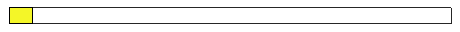

Elapsed time is 15.990348 seconds.


addpath Tool/VirtualSpeciesFunctions/
addpath Tool/
layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

Best Case

BC = 4;

disp("alpha:" + alpExp(BC) + ", " + "Samples:" + SampExp(BC) + ", " +  "Occupation:" + OccupExp(BC))

alpha:2, Samples:1000, Occupation:0.1


% N = 30;
N = 1;
% RN = randi([1 1000],[N, 1]);
showVirtual = true; 
T2=[];
for i = 1 : N
%     figure
    disp(i)
    j = RN(i);
    InfoInitialPoint= InitialPoint(Dimensions, Points(j, :)', Coeffs(j, :)');
    MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint, OccupExp(BC), showVirtual);
    NicheMap = MapInfo.Map;
    T = samplingVS(Dimensions, MapInfo, SampExp(BC), alpExp(BC), showVirtual, 'GenSP_' + string(i), true, true);
    T2 = [T2;T];
%     writetable(T,"CasesVirtualSpecies/Best/virtualBest_" + num2str(i) + '.csv');
%     drawnow
end

     1

     2

     3



writetable(T2,"CasesVS/virtualBest.csv");
save("CasesVS/BestSelectedMapsBC", "RN")

Worst Case

WC = 13;

disp("alpha:" + alpExp(WC) + ", " + "Samples:" + SampExp(WC) + ", " +  "Occupation:" + OccupExp(WC))

alpha:2, Samples:10, Occupation:0.7


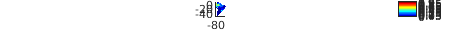

% N = 30;
N=1;
% RN = randi([1 1000],[N, 1]);
showVirtual = true; 
T2 = [];
for i = 1 : N
%     figure
    j = RN(i);
    InfoInitialPoint= InitialPoint(Dimensions, Points(j, :)', Coeffs(j, :)');
    MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint, OccupExp(WC), showVirtual);
    NicheMap = MapInfo.Map;
    T = samplingVS(Dimensions, MapInfo, SampExp(WC), alpExp(WC), false,'GenSP_' + string(i), true, true);
    T2 = [T2;T];
%     drawnow
end

writetable(T2,"CasesVS/virtualWorst.csv");
save("CasesVS/WorstSelectedMapsBC", "RN")